Confirmed_Path = "/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/COVID-19/csse_covid_19_data/csse_covid_19_time_series/time_series_covid19_confirmed_US.csv";
Deaths_Path = "/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/COVID-19/csse_covid_19_data/csse_covid_19_time_series/time_series_covid19_deaths_US.csv";

Confirmed_Cases = readtable(Confirmed_Path,'ReadVariableNames', 1, 'ReadRowNames', 1);

Deaths = readtable(Deaths_Path, 'ReadVariableNames', 1,'ReadRowNames', 1);

dates_og = Confirmed_Cases.Properties.VariableNames;
dates_og = dates_og(11:length(dates_og));
dates = []; 

for i=1:length(dates_og)
    date = char(dates_og(i));
    date = datetime(date(2:length(date)), 'InputFormat', 'MM_dd_yy');
    dates = [dates; date]; 
end 

LA_UID = '84006037'; 
LA_County_population = 10040000; 
SEA_UID = '84053033'; 
SEA_County_population = 2253000; 

% Array of confirmed cases and deaths in LA 
LA_Confirmed = table2array(Confirmed_Cases(LA_UID,[11:width(Confirmed_Cases)]));
LA_Confirmed_N = LA_Confirmed./LA_County_population; 
LA_Deaths = table2array(Deaths(LA_UID,[12:width(Deaths)]));
LA_Deaths_N = LA_Deaths./LA_County_population; 

% Array of confirmed cases and deaths in Seattle
SEA_Confirmed = table2array(Confirmed_Cases(SEA_UID,[11:width(Confirmed_Cases)]));
SEA_Confirmed_N = SEA_Confirmed./SEA_County_population; 
SEA_Deaths = table2array(Deaths(SEA_UID,[12:width(Deaths)]));
SEA_Deaths_N = SEA_Deaths./SEA_County_population; 

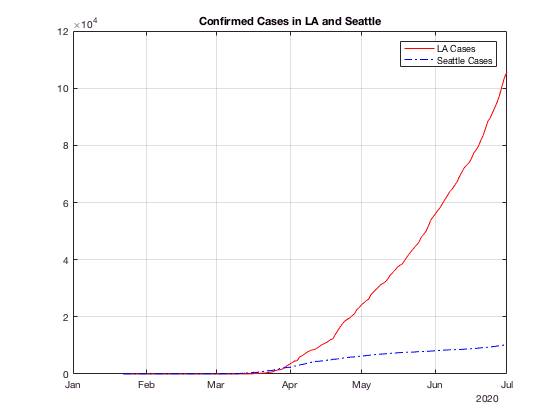

plot(dates, LA_Confirmed, '-r')
hold on; 
plot(dates, SEA_Confirmed, '-.b')
grid on; 
title('Confirmed Cases in LA and Seattle')
legend('LA Cases', 'Seattle Cases')
hold off; 

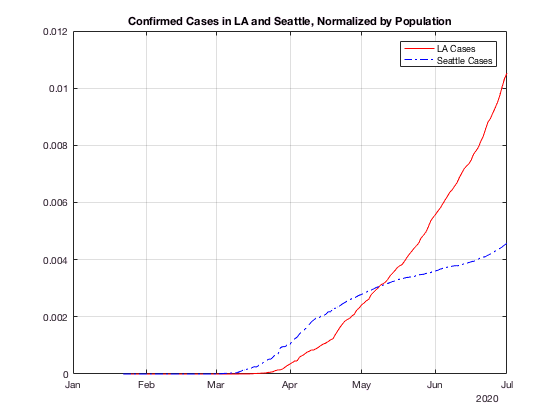


plot(dates, LA_Confirmed_N, '-r')
hold on; 
plot(dates, SEA_Confirmed_N, '-.b')
grid on; 
title('Confirmed Cases in LA and Seattle, Normalized by Population')
legend('LA Cases', 'Seattle Cases')
hold off; 

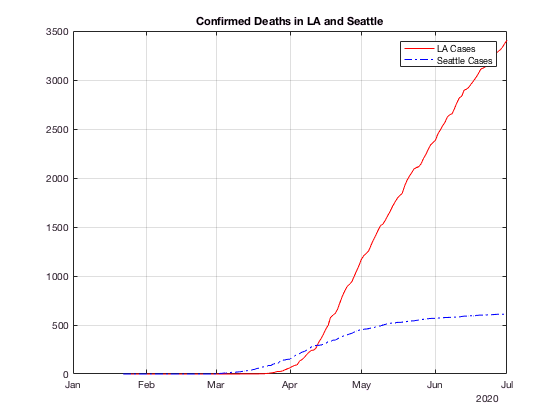


plot(dates, LA_Deaths, 'r')
hold on; 
plot(dates, SEA_Deaths, '-.b')
grid on; 
title('Confirmed Deaths in LA and Seattle')
legend('LA Cases', 'Seattle Cases')
hold off; 

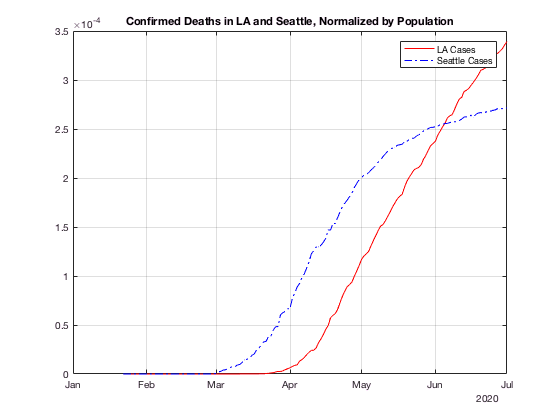


plot(dates, LA_Deaths_N, 'r')
hold on; 
plot(dates, SEA_Deaths_N, '-.b')
grid on; 
title('Confirmed Deaths in LA and Seattle, Normalized by Population')
legend('LA Cases', 'Seattle Cases')
hold off; 